# Settlement

**Overview**

The `Settlement` chart displays the option prices against strike price. The option prices comprise put prices below the at-the-money (ATM) price, and call prices above the ATM price. The ATM price, i.e., where the call and put prices are equal, is highlighted by the call-put parity line. 

The chart data are:

- `Price`, $S$: the current price of the underlying asset.

- `Strike`, $K$: the strike (i.e., exercise) price of the option, expressed as an increasing vector.

- `Rate`, $r$: the annualized continuously compounded risk-free rate of return over the life of the option, expressed as a positive decimal number.

- `Time`, $T$: the time to expiry of the option, expressed in years.

- `Volatility`, $\sigma$: the annualized asset price volatility (i.e., the annualized standard deviation of the continuously compounded asset return), expressed as a positive decimal number.

- `Yield`**, **$q$: the annualized continuously compounded yield of the underlying asset over the life of the option, expressed as a decimal number. 

These inputs are then used to compute the values of the *European put and call option prices* using the Black-Scholes model, given by the following equations:


$$C = S \cdot\Phi{ \left( d_1 \right) } - K e^{ -(r + q) T }  \Phi{ \left( d_2 \right) } \\
P = K e^{-( r + q) T }  \Phi{ \left( - d_2 \right) } - S \cdot \Phi{ \left( - d_1 \right) }$$


where $\Phi$ is the cumulative distribution function for the standard normal distribution ([normcdf](matlab: doc( "normcdf" ))) and:


$$d_1 = \frac{ \log{ \left( \frac{ S }{ K } \right) } + \left( r + \frac{ \sigma^2 }{ 2 } \right) T }{ \sigma \sqrt{ T } }, \quad
d_2 = d_1 - \sigma \sqrt{ T }.$$


Note that any of the inputs listed above can be omitted. This will result in the use of default values, which are defined as:

- *Strike*: 85 to 115 with spacing of 1

- *Underlying asset price*: 100

- *Rate*: 0.05

- *Time*: 0.25 years

- *Volatility*: 0.5

- *Yield*: 0

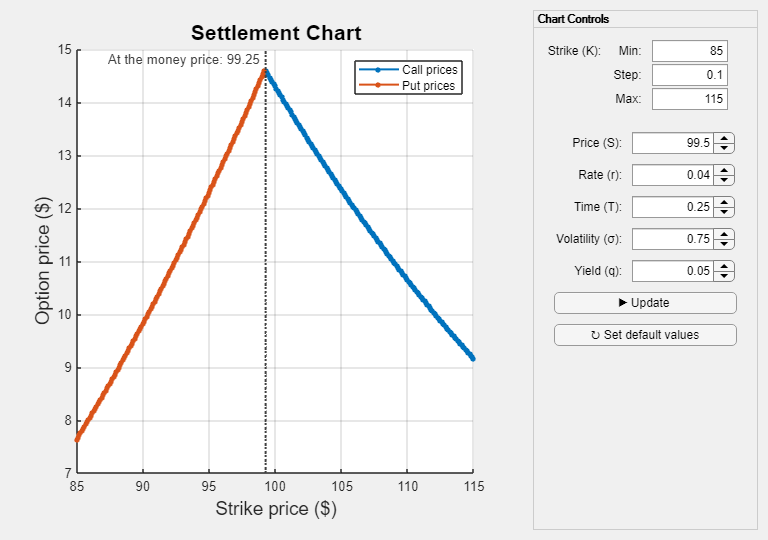

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "Settlement.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "Settlement.m"))) the source code for the `Settlement` chart.

Documentation for:

- [`blsprice`](matlab: doc( "blsprice" )): Black-Scholes call and put option pricing

- [`normcdf`](matlab: doc( "normcdf" )): Normal cumulative distribution function

## Define input data for the chart.

Strike prices, defined in currency units, e.g., $US.

Strike = (85:0.1:115).';

The price of the underlying asset, defined in currency units.

Price = 100;

Risk-free interest rate, expressed as a decimal number between 0 and 1.

Rate = 0.04;

Time to expiry, expressed in years.

Time = 0.25;

Volatility, expressed as a decimal number between 0 and 1.

Volatility = 0.45;

Dividend yield, expressed as a decimal number between 0 and 1.

Yield = 0.01;

## Create a figure for the chart.

f = exampleFigure( "Name", "Settlement Example" );

## Create the chart.

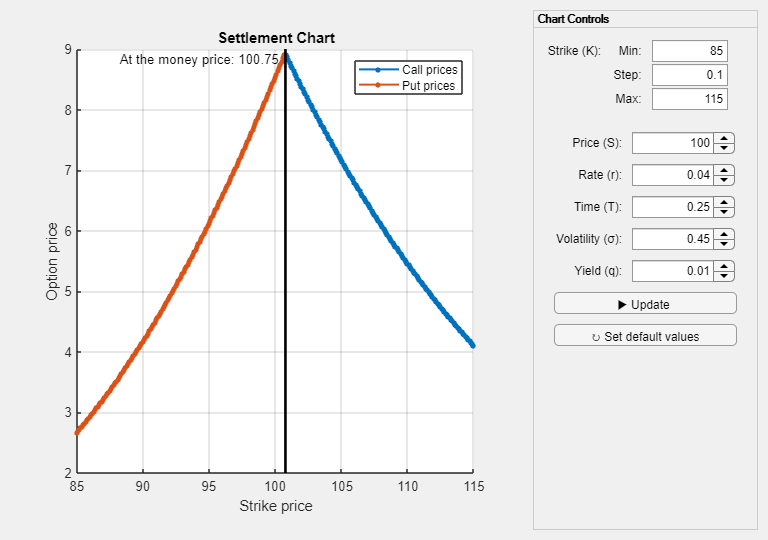

SC = chart.Settlement( "Parent", f, ...
    "Units", "normalized", ...
    "Position", [0, 0, 1, 1], ...
    "Strike", Strike, ...
    "Price", Price, ...
    "Rate", Rate, ...
    "Time", Time, ...
    "Volatility", Volatility, ...
    "Yield", Yield );

## Access the option prices from the chart.

The corresponding call and put option prices are computed by the chart using the Black-Scholes model. We can access these using the `OptionPrices` chart property. This is a 2-column matrix containing the call and put prices in its columns, respectively.

CallPrices = SC.OptionPrices(:, 1);
PutPrices  = SC.OptionPrices(:, 2);

The *at-the-money price*, where the call and put prices intersect, is also computed by the chart. We can query the chart property `AtTheMoneyPrice` to retrieve this. It is also displayed in the label of the constant line plotted on the chart's axes.

disp( "At-the-money price: " + num2str( SC.AtTheMoneyPrice, "%.2f" ) )

At-the-money price: 100.75


## Adjust the chart data.

We can adjust any of the chart's data properties, including after the chart has been created.

For instance, we can change the underlying asset price.

SC.Price = 99.5;

Multiple properties can be adjusted using the [set](matlab: doc( "set" )) command.

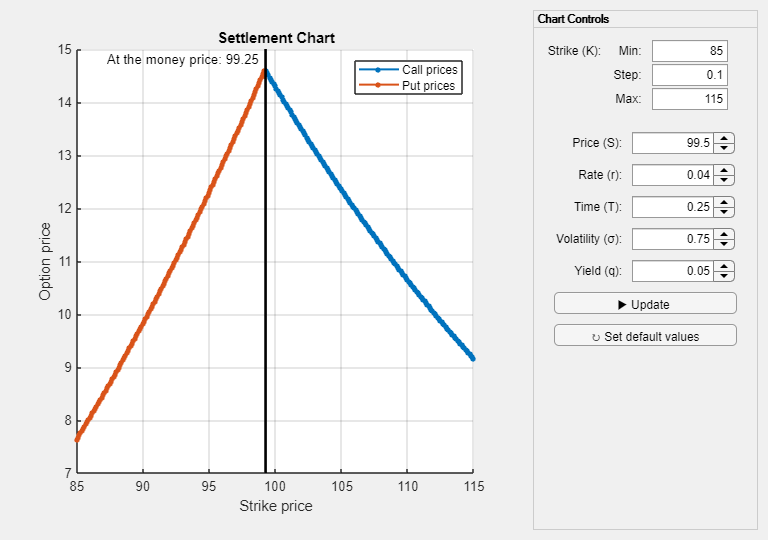

set( SC, "Volatility", 0.75, "Yield", 0.05 )

The chart's graphics and controls update automatically.

Display the new at-the-money price.

disp( "At-the-money price: " + num2str( SC.AtTheMoneyPrice, "%.2f" ) )

At-the-money price: 99.25


## Customize the chart appearance.

We can customize the chart appearance to meet our requirements. For instance, we can update the chart's annotations.

xlabel( SC, "Strike price ($)", "FontSize", 14 )
ylabel( SC, "Option price ($)", "FontSize", 14 )
title( SC, "Settlement Chart", "FontSize", 16 )

We can also adapt various decorative properties of the lines.

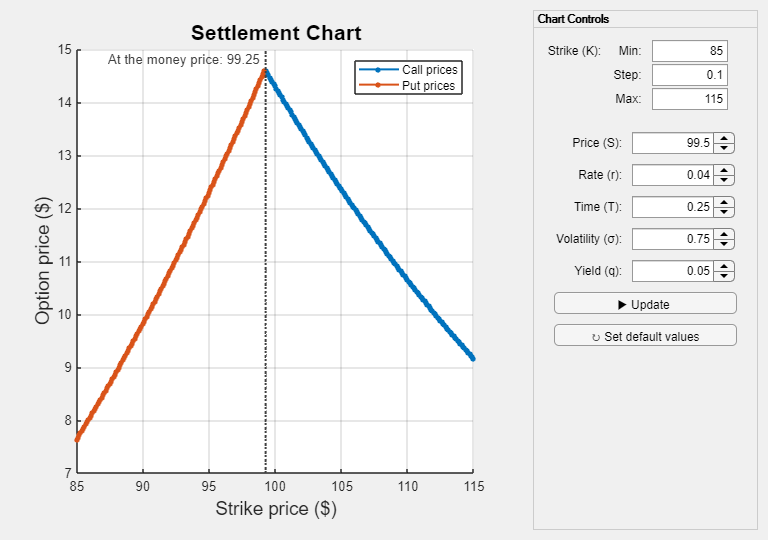

set( SC, "CallLineWidth", 1.5, ...
    "PutLineWidth", 1.5, ...
    "AtTheMoneyColor", [0.25, 0.25, 0.25], ...
    "AtTheMoneyLineWidth", 1.5, ...
    "AtTheMoneyLineStyle", ":" )

## Chart interactivity.

We can hide or show the chart's control panel via the `Controls` property.

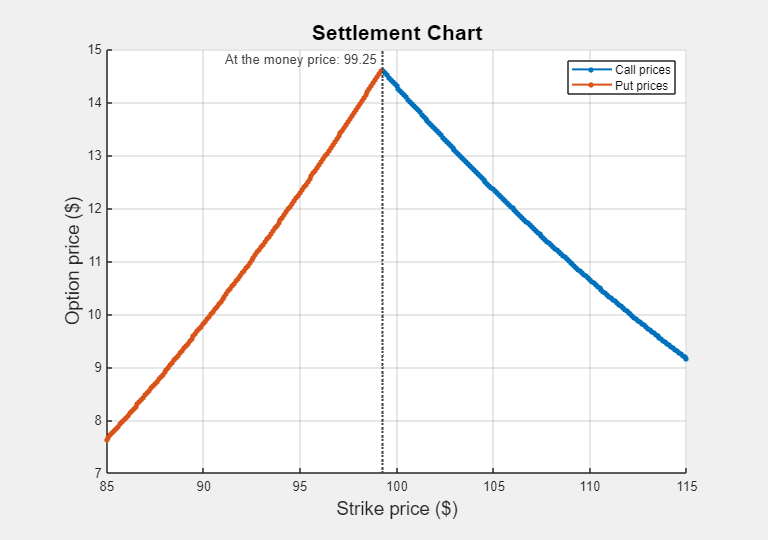

SC.Controls = "off";

## Reset the chart.

The control panel includes a button for restoring the default chart data. Programmatically, this is equivalent to invoking the chart's `reset` method.

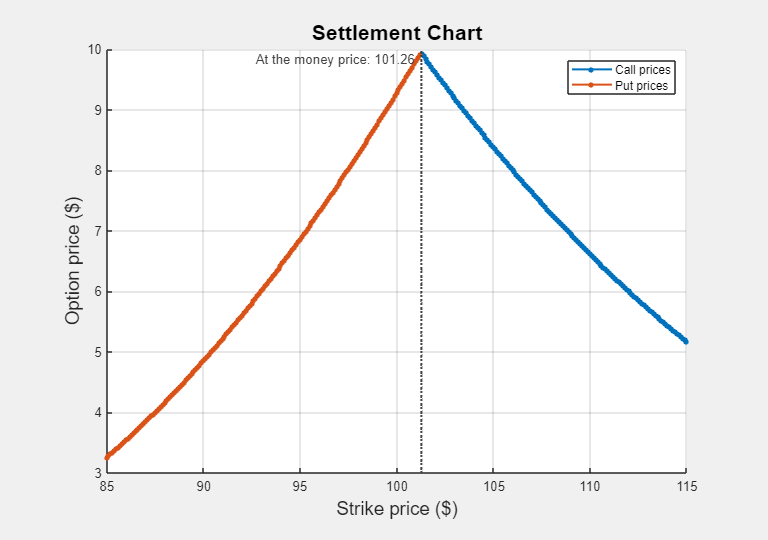

reset( SC )

*Copyright 2019-2021 The MathWorks, Inc.*